num_trials = 500;
total_flow_rate = zeros(num_trials,1)

for trial = 1:num_trials
    %{
    % Parameter Set OG (in Ruben's code)
    Lx = 200;
    Ly = 100;
    Nx = 100;
    Ny = 200;
    lx = 60;
    ly = 30;
    bmin = 1e-3;
    bmax = 5e-3;
    visc = 1e-3;
    pinlet = 1e5;
    poutlet = 0;
    tol = 1e-12;
    seed = NaN;
    %}

    %{
    Lx, Ly are dimension lengths in m.
      ?
    Nx, Ny are #x-fractures, #y-fractures.                                        
      Should have Nx in [0.1*Lx,10*Lx].
    lx, ly are maximal lengths of x-fractures, y-fractures.
      Should be in [20,30] m.
    bmin, bmax are min and max fracture gap widths, approximated as 0 in plots.
      Should be 0.01e-3 m and 0.3e-3 m.
    visc is fluid velocity.
      Should be 1e-3 Pa*s.
    pinlet, poutlet are the boundary pressures.
      Should be 1e5 Pa and 0 Pa.
    %}

    % Parameter Set 0 (Lluis-reccomended)
    Lx = 150;
    Ly = 150;
    Nx = Lx;
    Ny = Ly;
    lx = 20;
    ly = 20;
    bmin = 0.01e-3;
    bmax = 0.3e-3;
    visc = 1e-3;
    pinlet = 1e5;
    poutlet = 0;
    tol = 1e-12;
    seed = NaN;

     
    % Parameter Set 0' (Lluis-recommended, but with lx, ly = 40 to make the boundaries connected, since 30 was insufficient; used as baseline for param sets 1 through 4)
    lx = 40;
    ly = 40;
    
    %{
    % Parameter Set 1 (Lluis recommended 0.1*Lx, but we need a higher amount to connect boundaries)
    Nx = 0.5*Lx
    %}

    %{
    % Parameter Set 2
    Nx = 10*Lx;
    %}

    %{
    % Parameter Set 3
    lx = 50;
    ly = 50;
    %}

    %{
    % Parameter Set 4
    lx = 60;
    ly = 60;
    %}

   [total_flow_rate(trial)] = run_trial(Lx, Ly, Nx, Ny, lx, ly, bmin, bmax, visc, pinlet, poutlet, tol, seed);
   if mod(trial,20) == 0
       fprintf('Trial %d: total_flow_rate = %.3e\n', trial, total_flow_rate(trial));
   end
   
end

Trial 20: total_flow_rate = 1.261e-05
Trial 40: total_flow_rate = 1.421e-05
Trial 60: total_flow_rate = 1.283e-05
Trial 80: total_flow_rate = 1.759e-05
Trial 100: total_flow_rate = 1.526e-05
Trial 120: total_flow_rate = 1.243e-05
Trial 140: total_flow_rate = 5.173e-06


Trial 160: total_flow_rate = 1.292e-05
Trial 180: total_flow_rate = 1.037e-05
Trial 200: total_flow_rate = 1.310e-05
Trial 220: total_flow_rate = 1.188e-05
Trial 240: total_flow_rate = 1.169e-05
Trial 260: total_flow_rate = 1.085e-05
Trial 280: total_flow_rate = 1.364e-05
Trial 300: total_flow_rate = 1.499e-05
Trial 320: total_flow_rate = 1.551e-05
Trial 340: total_flow_rate = 1.599e-05
Trial 360: total_flow_rate = 1.524e-05
Trial 380: total_flow_rate = 1.653e-05
Trial 400: total_flow_rate = 1.527e-05
Trial 420: total_flow_rate = 8.830e-06
Trial 440: total_flow_rate = 1.259e-05
Trial 460: total_flow_rate = 1.242e-05
Trial 480: total_flow_rate = 1.061e-05
Trial 500: total_flow_rate = 1.380e-05


figure(5); clf

translucencyConst = 0.1;

% prior to 9/24: nums_trials = [10, 100, 300, 500, 1000, 2000];
nums_trials = [500, 350, 250, 100, 50, 10];
colors = ['m', 'r', 'y', 'g', 'c', 'b'];
translucencies = [0.11, 0.12, 0.13, 0.14, 0.15, 0.16];
graphs = gobjects(1,6);
for j=1:6
    % [graphs(2*j-1),graphs(2*j)] = create_plot_and_histogram(total_flow_rate,nums_trials(j), colors(j)+"-", colors(j), translucencyConst, 30);
    [graphs(j)] = create_plot_and_histogram(total_flow_rate,nums_trials(j), colors(j)+"-", colors(j), translucencies(j), 30)
end

graphs =   1×6 graphics array:

    Histogram              GraphicsPlaceholder    GraphicsPlaceholder    GraphicsPlaceholder    GraphicsPlaceholder    GraphicsPlaceholder


graphs =   1×6 graphics array:

    Histogram              Histogram              GraphicsPlaceholder    GraphicsPlaceholder    GraphicsPlaceholder    GraphicsPlaceholder


graphs =   1×6 graphics array:

    Histogram              Histogram              Histogram              GraphicsPlaceholder    GraphicsPlaceholder    GraphicsPlaceholder


graphs =   1×6 graphics array:

    Histogram              Histogram              Histogram              Histogram              GraphicsPlaceholder    GraphicsPlaceholder


graphs =   1×6 graphics array:

    Histogram              Histogram              Histogram              Histogram              Histogram              GraphicsPlaceholder


graphs =   1×6 Histogram array:

    Histogram    Histogram    Histogram    Histogram    Histogram    Histogram


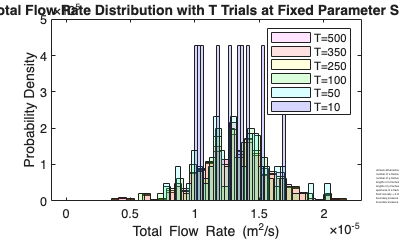

% legend(graphs, {'T=10','T=10','T=20','T=20', 'T=40', 'T=40', 'T=60', 'T=60', 'T=80', 'T=80', 'T=100', 'T=100'})
% legend(graphs, {'T=10','T=10','T=100','T=100', 'T=300', 'T=300', 'T=500', 'T=500', 'T=1000', 'T=1000', 'T=2000', 'T=2000'})
legend(graphs, {'T=500','T=350','T=250','T=100', 'T=50', 'T=10'})


statsText = sprintf('Max = %5.e \n Min = %.5e \n Mean = %.5e \n Standard Deviation = %.5e', max(total_flow_rate),min(total_flow_rate),mean(total_flow_rate), std(total_flow_rate));
parametersText = "domain dimensions = (" + Lx + ", " + Ly + ") m " + newline +...
    "number of x-fractures = " + Nx + newline +...
    "number of y-fractures = " + Ny + newline +...
    "lengths of x-fractures in [0," + lx + "] m" + newline +...
    "lengths of y-fractures in [0," + ly + "] m" + newline +...
    "apertures of x-fractures in [" + bmin + ", "+bmax + "] m" + newline +...
    "fluid viscosity = " + visc + newline +...
    "boundary pressure at inlet = "+pinlet+" Pa" + newline +...
    "boundary pressure at outlet = "+poutlet+" Pa";
titleText = "Total Flow Rate Distribution with T Trials at Fixed Parameter Set 2";
axpos = get(gca,'Position');
annotation('textbox', ...
    'String', statsText, ...
    'FontSize', 5, ...
    'Units', 'normalized', ...
    'EdgeColor', 'none', ...
    'HorizontalAlignment', 'left', ...
    'FitBoxToText', 'on', ...
    'Position', [axpos(1), axpos(2)-0.2, axpos(3), 0.05]);
annotation('textbox', ...
    'String', parametersText, ...
    'FontSize', 2, ...
    'Units', 'normalized', ...
    'EdgeColor', 'none', ...
    'HorizontalAlignment', 'left', ...
    'FitBoxToText', 'on', ...
    'Position', [axpos(1)+axpos(3)+0.02, axpos(2), 0.2, 0.2]); 
title(titleText)

xlabel("Total Flow Rate (m^2/s)")
ylabel("Probability Density")

save(fullfile('Total Flow Rate Distribution with T Trials at Fixed Parameters (No Continuous Curve)', 'Parameter Set 2.mat'),'total_flow_rate')
save_figure(5,'Total Flow Rate Distribution with T Trials at Fixed Parameters (No Continuous Curve)','T Trials, Parameter Set 2')